# Simple Image Editor using Spacial Filtering

**Select a filter type**

filterType = 'lowpass';

**Select an image file**

Enter the filename of the image to be used, including its file extension *(ex. img9.jpg)*.

filename = 'img9.jpg';
sampleImage = imread(filename);

**Convert image to grayscale**

See converted grayscale image in comparison to the original image.

imageRaw = rgb2gray(sampleImage);
imageSize = size(imageRaw);

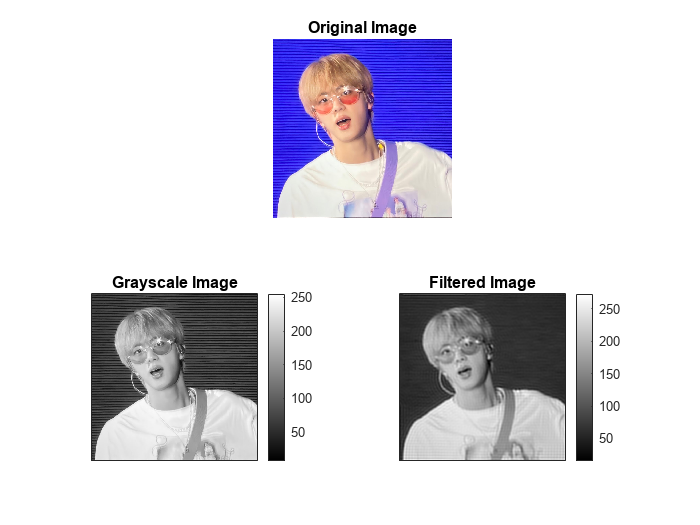

% Display images
colormap gray;
colorbar;
subplot(2,3,[1 3])

imshow(sampleImage)
title("Original Image")

subplot(2,2,[1 2]);

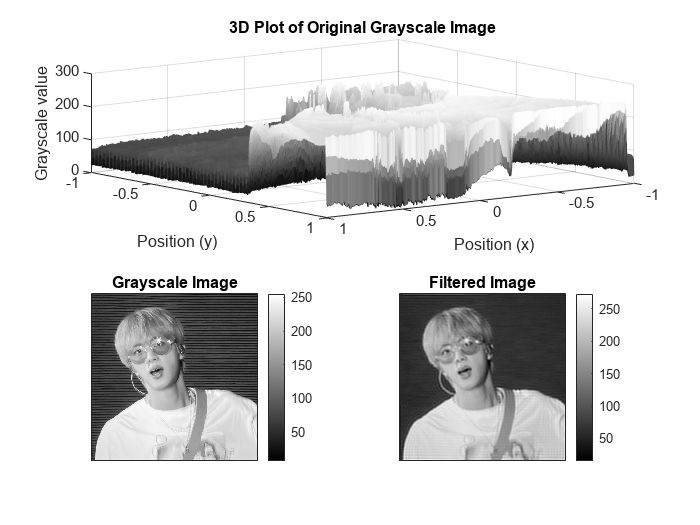

mesh(f1,f2,imageRaw);
% Note: f1 and f2 are improvised vectors to enable 3D plot visualization
title('3D Plot of Original Grayscale Image');
set(gca,'XDir','reverse','YDir','reverse');
xlabel('Position (x)');
ylabel('Position (y)');
zlabel('Grayscale value');

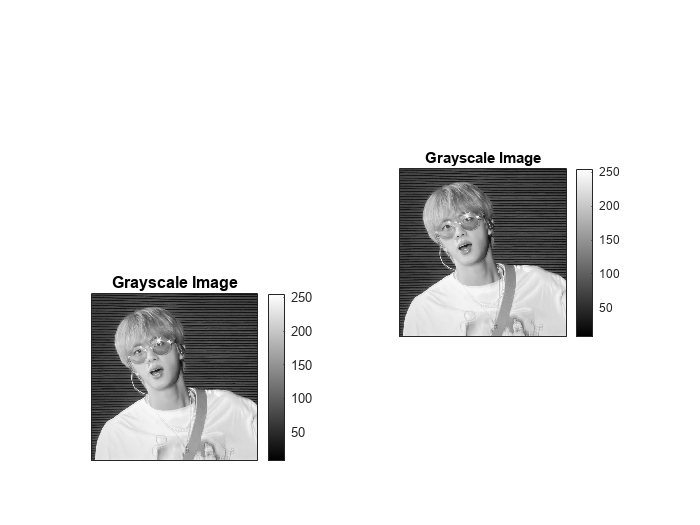


subplot(1,2,2)
imagesc(imageRaw)
colorbar;
axis square;
set(gca,'xtick',[],'ytick',[]);
title("Grayscale Image")

**Prepare image data for spacial filtering using 2D Fast Fourier Transform (FFT)**

Generate the two-dimensional frequency vectors for an `m`-by-`n` matrix, where `m` and `n` are the dimensions of the sample image.

[f1,f2] = freqspace(imageSize,'meshgrid'); 
% Note: freqspace was used because freqz2 is only limited to 64x64

Compute the distance of each element from the center.

r = sqrt(f1.^2 + f2.^2)

r =     1.4142    1.4127    1.4113    1.4098    1.4083    1.4069    1.4054    1.4039    1.4025    1.4010    1.3996    1.3981    1.3966    1.3952    1.3937    1.3923    1.3908    1.3894    1.3880    1.3865    1.3851    1.3836    1.3822    1.3807    1.3793    1.3779    1.3764    1.3750    1.3736    1.3722    1.3707    1.3693    1.3679    1.3665    1.3650    1.3636    1.3622    1.3608    1.3594    1.3580    1.3566    1.3552    1.3538    1.3524    1.3510    1.3496    1.3482    1.3468    1.3454    1.3440
    1.4127    1.4113    1.4098    1.4083    1.4069    1.4054    1.4039    1.4025    1.4010    1.3995    1.3981    1.3966    1.3952    1.3937    1.3922    1.3908    1.3893    1.3879    1.3865    1.3850    1.3836    1.3821    1.3807    1.3792    1.3778    1.3764    1.3749    1.3735    1.3721    1.3706    1.3692    1.3678    1.3664    1.3649    1.3635    1.3621    1.3607    1.3593    1.3579    1.3564    1.3550    1.3536    1.3522    1.3508    1.3494    1.3480    1.3466    1.3452    1.3438    1

Get the two-dimensional Fast Fourier Transform using `fft2` function.

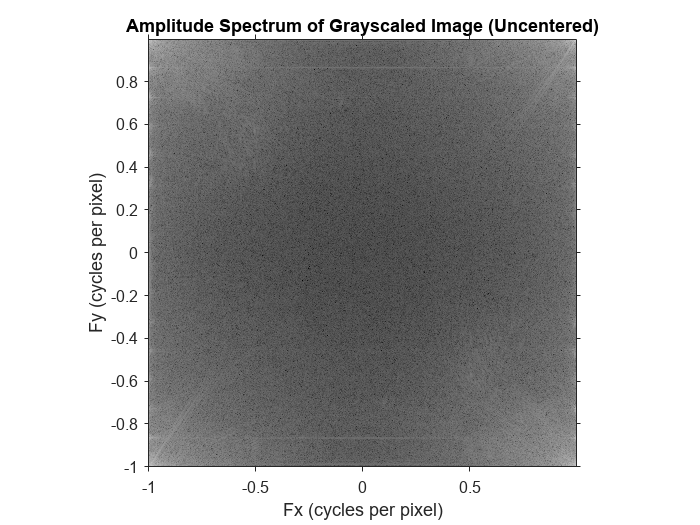

fftRaw = fft2(imageRaw);

% Tuning of data for visualization
temp = abs(fftRaw);
temp(temp<10^-10) = 10^-10; 
temp = log10(temp);

% Visualization
figure;
colormap gray;
imagesc(mean(f1),mean(f2,2),temp);
title('Amplitude Spectrum of Grayscaled Image (Uncentered)');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('Fx (cycles per pixel)');
ylabel('Fy (cycles per pixel)');

Shift the zero-frequency component to the center of spectrum using `fftshift` function.

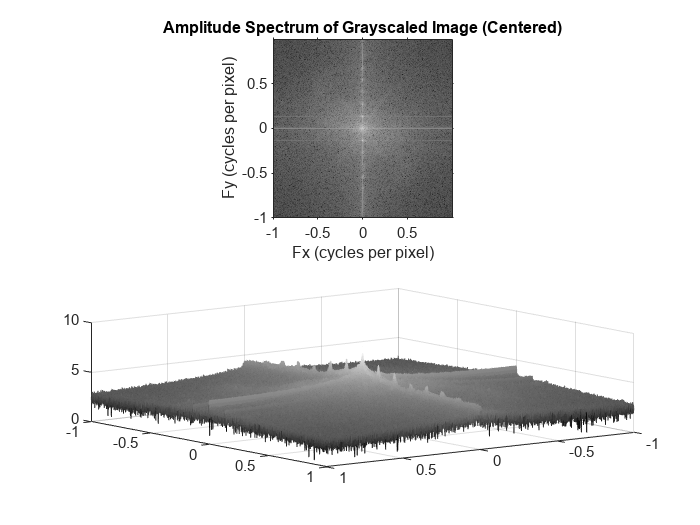

fftRaw = fftshift(fftRaw);

% Tuning of data for visualization
temp = abs(fftRaw);
temp(temp<10^-10) = 10^-10; 
temp = log10(temp);

% Visualization
figure;
colormap gray;
subplot(2,1,1)
imagesc(mean(f1),mean(f2,2),temp);
title('Amplitude Spectrum of Grayscaled Image (Centered)');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('Fx (cycles per pixel)');
ylabel('Fy (cycles per pixel)');
subplot(2,1,2)
mesh(f1,f2,temp);
%title('');
set(gca,'XDir','reverse','YDir','reverse')

**Design a filter template**

Create a matrix of ones with the same size as the image.

filt = ones(size(f1))

filt =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

maxrValue = max(r,[],"all");
minrValue = min(r,[],"all");
midrValue1 = maxrValue/2; % default value

**Set cut-off frequencies**

If **Smoothen Image (Lowpass Filter)** or **Isolate Sharpness (Highpass Filter)** is selected, `cutoff1` frequency will be set as its cut-off frequency. 

- For **Smoothen Image**, the lower the cut-off frequency, the smoother the image. 

- For **Isolate Sharpness**, the higher the cut-off frequency, the more isolated the sharpness becomes. To put it differently, the higher the cut-off frequency, the more abstract or unrecognizable the filtered image becomes in comparison to the original grayscale image.

Otherwise, if **Bandpass** or **Bandstop Filter** is selected, `cutoff1` frequency will be the lower limit of the cut-off frequency range.

cutoff1 = 0.12;

If **Bandpass** or **Bandstop Filter** is selected, `cutoff2` frequency will be the upper limit of the cut-off frequency range. Otherwise, if **Smoothen Image **or **Isolate Sharpness** is selected, this value will be disregarded. The slider for the upper limit cut-off frequency is configured such that its value does not fall below the lower limit set in `cutoff1`.

midrValue2 = (maxrValue-cutoff1)/2; % default value
% Set upper limit of cut-off frequency range
cutoff2 = 1.02;

**Create the filter**

Based on the selected filter type, build the filter by setting the values outside of the desired cut-off frequency to zero. 

switch filterType
    case 'lowpass'
        filt(r>cutoff1) = 0
    case 'highpass'
        filt(r<cutoff1) = 0
    case 'bandpass'
        filt((r<cutoff2)|(r>cutoff1)) = 0
    case 'bandstop'
        filt((r>cutoff2)|(r<cutoff1)) = 0
end

filt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

**Apply spacial filtering **

Multiply the generated filter by the 2D Fast Fourier Transform of the grayscale image.

% Apply filter on image
filteredFFT = filt.*fftRaw

filteredFFT = 1.0e+08 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.

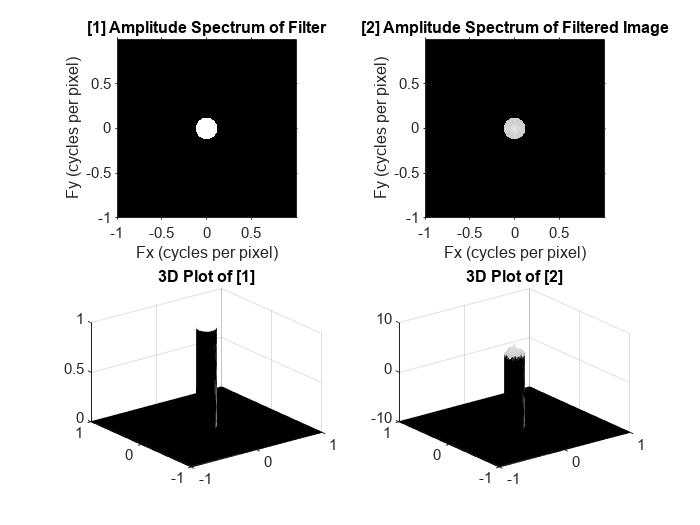

% Visualization
figure;
colormap gray;
subplot(2,2,1);
imagesc(mean(f1),mean(f2,2),abs(filt));
title('[1] Amplitude Spectrum of Filter');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('Fx (cycles per pixel)');
ylabel('Fy (cycles per pixel)');

temp = abs(filteredFFT);
temp(temp < 10^-10) = 10^-10; 
temp = log10(temp); 

subplot(2,2,2)
imagesc(mean(f1),mean(f2,2),temp);
title('[2] Amplitude Spectrum of Filtered Image');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('Fx (cycles per pixel)');
ylabel('Fy (cycles per pixel)');

subplot(2,2,3);
mesh(f1,f2,filt);
title('3D Plot of [1]');

subplot(2,2,4)
mesh(f1,f2,temp);
title('3D Plot of [2]');

**Reconstruct the image **

Rebuild the image from the filtered FFT using the `ifftshift` and `ifft2` functions. 

% Undo fftshift
filteredImage = ifftshift(filteredFFT); 
% Undo fft2
filteredImage = ifft2(filteredImage);
filteredFFT = abs(filteredFFT);

**Output**

Here is a full comparison of the images processed throughout. 

*Pick a colormap to see the grayscale images using different colormaps. Colormaps only vary the presentation of data, and does not alter the data.*

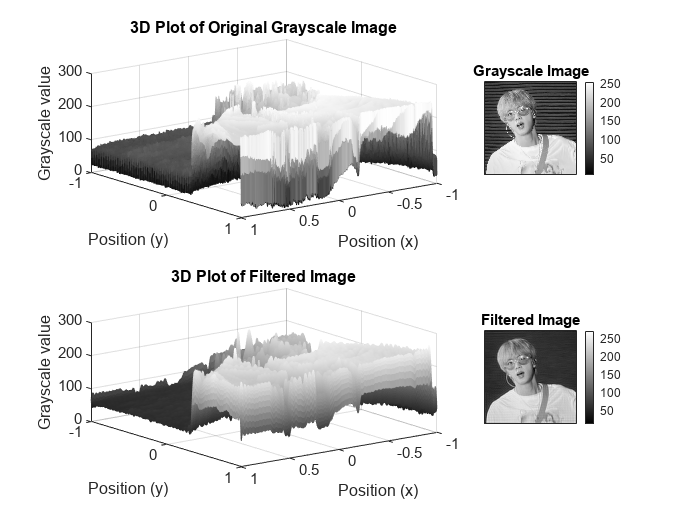

% Visualization
figure;
colormap gray;

subplot(2,3,[1 2]);
mesh(f1,f2,imageRaw);
% Note: f1 and f2 are improvised vectors to enable 3D plot visualization
title('3D Plot of Original Grayscale Image');
set(gca,'XDir','reverse','YDir','reverse');
xlabel('Position (x)');
ylabel('Position (y)');
zlabel('Grayscale value');

subplot(2,3,3)
imagesc(imageRaw)
colorbar;
axis square;
set(gca,'xtick',[],'ytick',[]);
title("Grayscale Image")

subplot(2,3,[4 5]);
mesh(f1,f2,filteredImage);
% Note: f1 and f2 are improvised vectors to enable 3D plot visualization
title('3D Plot of Filtered Image');
set(gca,'XDir','reverse','YDir','reverse');
xlabel('Position (x)');
ylabel('Position (y)');
zlabel('Grayscale value');

subplot(2,3,6)
imagesc(filteredImage);
title('Filtered Image');
colorbar;
axis square
set(gca,'xtick',[],'ytick',[]);


% Image Visualization
figure;

% Aesthetics
colormap gray;

subplot(2,2,[1 2])
imshow(sampleImage)
title("Original Image")

subplot(2,2,3)
imagesc(imageRaw)
colorbar;
axis square;
set(gca,'xtick',[],'ytick',[]);
title("Grayscale Image")

subplot(2,2,4)
imagesc(filteredImage);
title('Filtered Image');
colorbar;
axis square
set(gca,'xtick',[],'ytick',[]);